# DFGLS Function Tutorial

#### Contents

- 1. Intro

- 2. Data

- 3. DF-GLS unit-root Tests

-     A. GDP in levels

-     B. GDP QoQ (log-transformed first-differences)

- 4. Comparison to Stata®'s *dfgls* function

### Intro

The `DFGLS` function implements unit-root testing using the DF-GLS (ERS) test of Elliott, Rothenberg & Stock (1996), with 3 distinct methods for choosing the optimal lag-length in the underlying Augmented Dickey-Fuller (ADF) regression. The methods for selecting the optimal number of autoregressive lags are:

- Schwarz's Information Criterion (SIC)

- Modified Akaike Information Criterion (MAIC) proposed by Ng and Perron (2001)

- Sequential t-test (Seq-t) proposed by Ng and Perron (1995)

The output table from the `DFGLS` function, closely resembles the one produced by the corresponding Stata® command (dflgs). Specifically, for each of the 3 available methods for tuning the lag-order, the table shows: the selected optimal number of lags, the DFGLS test statistic, the number of observations included in the underlying ADF regressions, the RMSE, the critical values at the 1%, 5% and 10% levels of significance, and the (optimal) value of the information criterion. For the Seq-t method, the value reported under the IC column in the output table, corresponds to the P-value of the coefficient of the last lagged-term that was found to be statistically significant. Moreover, when no lagged terms in the ADF regressions are statistically significant, the entire row of the output table corresponding to the Seq-t method, will contain missing values (NaN's). Note that the rejection region for the insignificance of the lagged terms in the Seq-t method, is internally set to the 10% significance level.

Using input 'MethCVal', we can choose whether to return the critical values from Cheung & Lai (1995), or Elliott, Rothenberg & Stock (1996). When inputs 'Kmin' and/or 'Kmax' are not given by the user, those are set to 0 and to the value proposed by Schwert (1989), respectively. The recommendation in Schwert (1989) sets the **maximum** number of lags (Kmax) according to:

$K_{max} = 12(T/100)^{1/4}$  where $T$is the sample size. 

Setting input Trend=0, sets the alternative hypothesis ($H_A$) of the test, to the series being stationary around a mean.  Whereas, when Trend=1 (which is the default value), the formulation implies that under the $H_A$ the series is stationary around a linear time trend.

The DF-GLS (ERS) test is similar to the augmented Dickey-Fuller (ADF) test, with an additional step. Specifically, prior to fitting the model, we first transform (de-trend or de-mean, depending on $H_A$) the series via a generalized least-squares (GLS) regression. Elliott, Rothenberg and Stock (1996) show that this test has better power than the original ADF test.

%SYNTAX (with default input values): 
%out = DFGLS(Y,'Trend',1,'Kmin',0,'Kmax',[],'MethADF',1,'MethCVal','CL')
%out = DFGLS(Y) %Equivalent to above

%INPUTS:
%- Y: The timeseries to be tested for a unit root (i.e. a Tx1 vector or timetable)
%- Trend: Defines the alternative hypothesis (Ha) of the test.
%  - 0: Y is stationary around a mean
%  - 1: Y is stationary around a linear trend
%- Kmin: The minimum # of dYt-j terms in the ADF regression; if unspecified, Kmin=0
%- Kmax: The maximum # of dYt-j terms in the ADF regression; if unspecified, Kmax=floor(12*((T+1)/100)^(1/4))
%- MethADF: Specifies the method for selecting the obs included in the ADF regressions.
%            0 = use SAME # of obs (T-1-Kmax) across the ADF regressions for the different k's considered
%            1 = use varying # of obs (T-1-k) across the ADF regressions for the different k's considered
%- MethCVal: The method to use for retreiving the Critical Values.  
%            'CL'=Cheung & Lai (1995) 
%            'ERS'=Elliott, Rothenberg & Stock (1996)
%
%To replicate Stata's default settings, set: 
%out = DFGLS(Y,'Trend',1,'Kmin',1,'Kmax',[],'MethADF',0,'MethCVal','CL') 

### Data

To begin, let's download the latest U.S. real GDP time series using the FRED® API. To retrieve the time series we make use of another 3rd party function found on [MATLAB Exchange](https://mathworks.com/matlabcentral/fileexchange/116955-interface-to-easily-access-fred-data), `fred_api`.

%Use the FRED API to download the quarterly US real GDP (SeriesID: GDPC1)
[yt, Meta] = fred_api("GDPC1",'StartDate',datetime(2000,1,1),'EndDate',[]);

%Calculate the continuously-compounded quarter-on-quarter (QoQ) growth rate
gt = diff(log(yt{:,:}))*100;
gt = array2timetable(gt,"RowTimes",yt.Time(2:end),"VariableNames","GDPC1_growth");

%Align the timestamps (- remove the missing observation at the top)
y = synchronize(yt,gt,'intersection');

%Print the last 4 rows
tail(y,4) 

ans = 4×2 timetable
       Time       GDPC1    GDPC1_growth
    __________    _____    ____________
    01/04/2023    22225      0.50982   
    01/07/2023    22491       1.1868   
    01/10/2023    22679      0.83491   
    01/01/2024    22750      0.31077   

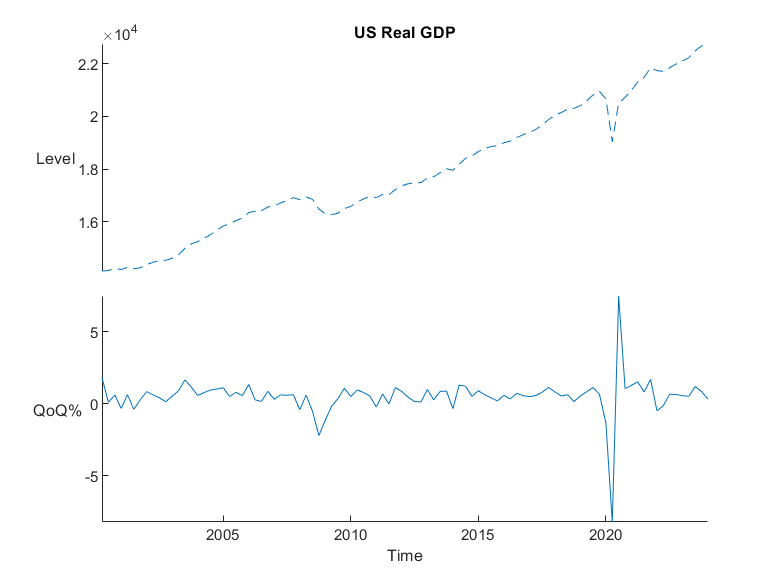

%Plot the series
p = stackedplot(y, {["GDPC1"]  "GDPC1_growth"});
p.DisplayLabels = {'Level', 'QoQ%'};
p.Title = 'US Real GDP';
p.LineProperties(1).PlotType = "plot";
p.LineProperties(1).LineStyle = "--"; 

### DF-GLS unit-root Tests 

#### A) GDP in levels

out = DFGLS(yt,'Trend',0,'Kmin',1,'Kmax',[],'MethADF',0,'MethCVal','CL')

The maximum lag chosen (using the Schwert criterion) is 11 


out = 3×9 table
     Method     Opt. Lag    DF-GLS    Obs    RMSE    1% C.Val.    5% C.Val.    10% C.Val.      IC  
    ________    ________    ______    ___    ____    _________    _________    __________    ______
    "SIC"           1       2.8959     85    268      -2.6012      -2.1333      -1.8274      11.287
    "MAIC"          1       2.8959     85    268      -2.6012      -2.1333      -1.8274      11.434
    "Seq. t"      NaN          NaN    NaN    NaN          NaN          NaN          NaN         NaN

Based on the resulted test statistic (column 3), the test fails to reject the H0 of a unit-root for all the reported levels of significance (columns 6-8) and for all the available methods of selecting the optimal lag-order (rows 1-3) in the underlying ADF regression. Since Kmax was not provided as input, `DFGLS` selected the maximum number of lags to be tested, using the Schwert criterion. As indicated in the text above the table, the Schwert criterion set Kmax=11. 

The NaN values in the sequential-t method (row 3) imply that all the (Kmax) lags tested in the underlying ADF regressions, were found to be statistically insignificant at the preselected (10%) significance level. This means that the Seq.t has selected an optimal lag-order of 0. However, since we set input parameter Kmin=1 (implying that the optimally selected K*=0 is outside the user-specified range), `DFGLS` returns NaN's to comply with the provided input values. Setting Kmin=0, would provide all the values in of the third row, with the exception of the last column (IC). 

#### B) GDP QoQ (log-transformed first-differences)

out = DFGLS(gt,'Trend',0,'Kmin',1,'Kmax',[],'MethADF',0,'MethCVal','CL')

The maximum lag chosen (using the Schwert criterion) is 11 


out = 3×9 table
     Method     Opt. Lag     DF-GLS     Obs     RMSE     1% C.Val.    5% C.Val.    10% C.Val.       IC   
    ________    ________    ________    ___    ______    _________    _________    __________    ________
    "SIC"           1        -5.0155    84      1.531     -2.6016      -2.1353      -1.8296       0.95728
    "MAIC"         11       -0.96343    84     1.3767     -2.6016      -1.9864       -1.688       0.99262
    "Seq. t"        4        -2.2002    84     1.4483     -2.6016      -2.0968      -1.7943      0.069416

Using the SIC criterion for the optimal lag length, the DFGLS test rejects the null of a unit-root at the 1% level of significance. Moreover, the seq-t method, rejects the null at the 5% significance level, and finally, setting the optimal number of lags to 11, as suggested by the MAIC criterion, implies that we might not have enough evidence for rejecting the unit-root null. 

#### Comparison to Stata®'s *dfgls* function

Using the same series as above, the pictures below report the output from Stata's DFGLS test applied on the levels, and the c.c. growth rate, respectively. In both cases, the DF-GLS statistic, the RMSE of the underlying ADF regression, the optimally selected lag order, and the values of the criteria, are all identical. 

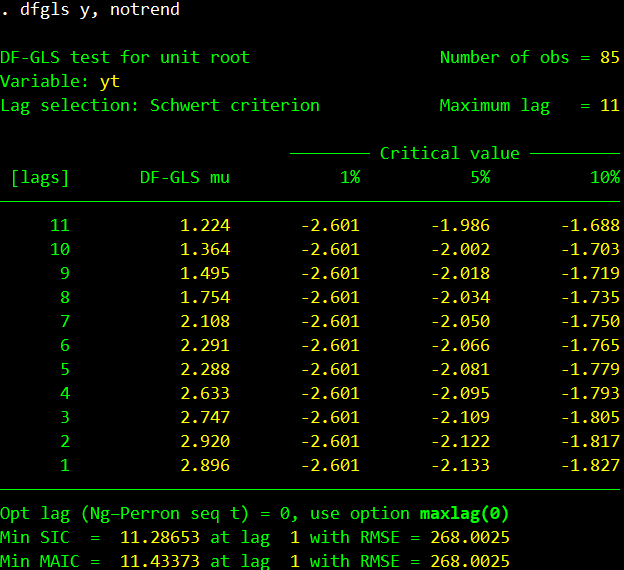

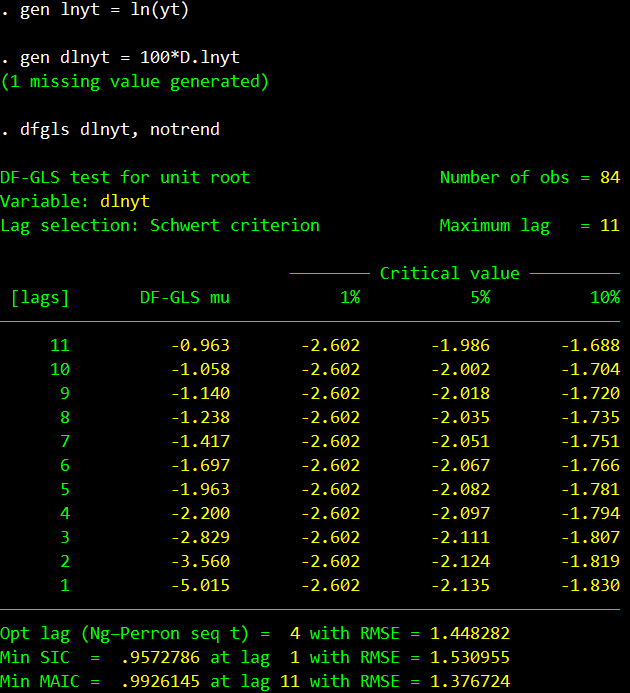

### References

Cheung, and Lai (1995), “Lag order and critical values of a modified Dickey–Fuller test.” *Oxford Bulletin of Economics and Statistics* 57, pp. 411–419.

Elliott, G. R., T. J. Rothenberg, and J. H. Stock, (1996), “Efficient tests for an autoregressive unit root.” *Econometrica,* 64, pp. 813–836. 

Ng, S., and Perron, P. (1995), “Unit Root Tests in ARMA Models with Data Dependent Methods for the Selection of the Truncation Lag.” *Journal of the American Statistical Association*, 90, pp. 268-281.

Ng, S., and Perron, P. (2001), “Lag Length Selection and the Construction of Unit Root Tests with Good Size and Power.”* Econometrica*, 69, pp. 1519-1554.

Schwert, W. (1989), “Tests for Unit Roots: A Monte Carlo Investigation.” *Journal of Business and Economic Statistics, *7, pp. 147–159.

Author: Haris Karagiannakis ([ckarag.github.io](http://ckarag.github.io))

If you are using this function for your research/thesis or teaching, please cite as: 

Karagiannakis, H. (2024), DFGLS for MATLAB (https://github.com/ckarag/**dfgls4matlab**)